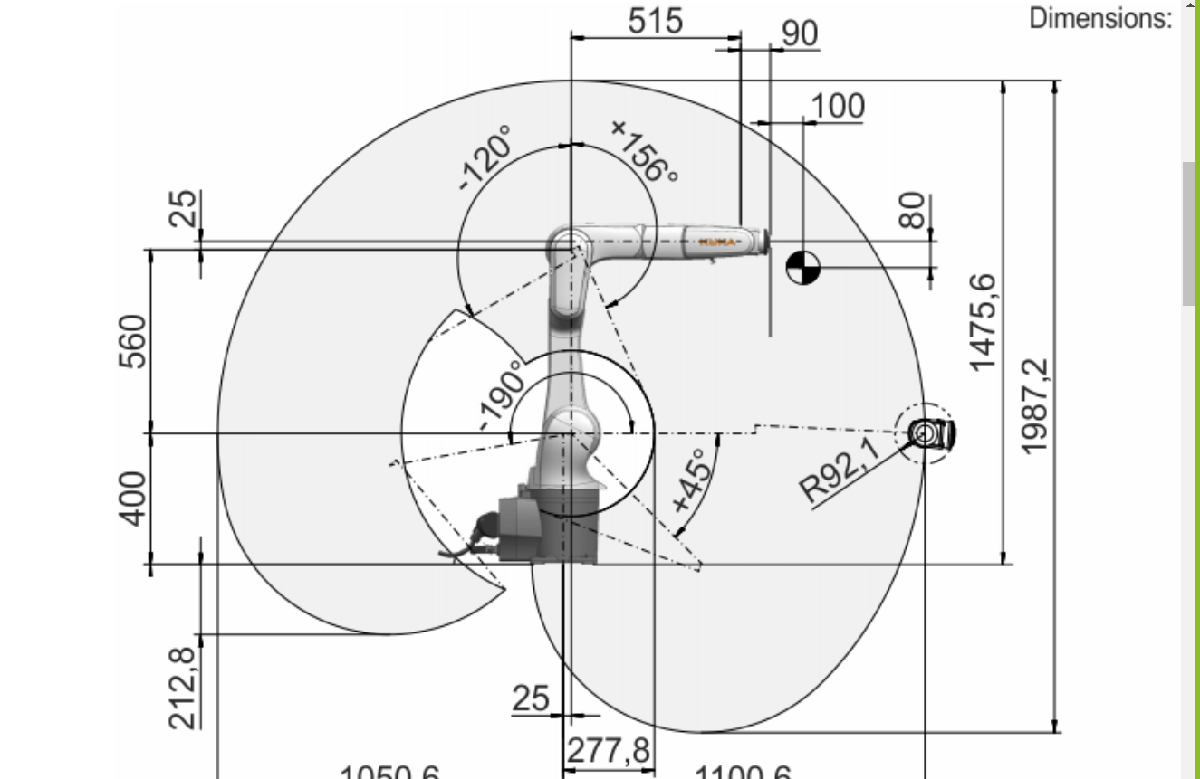

## The full solution will be provided in the functions and the test file

## Forward kinematics

syms q1 q2 q3 q4 q5 q6 d1 a1 a2 a3 d3
delta_q3 = atan(d3/a3)

$$delta\_q3 = \mathrm{atan}\left(\frac{d_{3}}{a_{3}}\right)$$

d3_dash = sqrt(d3^2 + a3^2)

$$d3\_dash = \sqrt{{a_{3}}^{2}+{d_{3}}^{2}}$$

H_transl = Rz(q1) * Tx(d1) * Tz(a1) * Ry(q2) * Tz(a2) * Ry(q3 - delta_q3) * Tx(d3_dash)*Ry(delta_q3);
simplify(H_transl)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \frac{\cos\left(q_{1}\right)\,\sigma_{3}}{\sigma_{1}} & -\sin\left(q_{1}\right) & \frac{\cos\left(q_{1}\right)\,\sigma_{4}}{\sigma_{1}} & \cos\left(q_{1}\right)\,\sigma_{5}\\ \frac{\sin\left(q_{1}\right)\,\sigma_{3}}{\sigma_{1}} & \cos\left(q_{1}\right) & \frac{\sin\left(q_{1}\right)\,\sigma_{4}}{\sigma_{1}} & \sin\left(q_{1}\right)\,\sigma_{5}\\ -\frac{\sigma_{4}}{\sigma_{2}} & 0 & \frac{\sigma_{3}}{\sigma_{2}} & a_{1}+a_{2}\,\cos\left(q_{2}\right)-\sin\left(\sigma_{7}\right)\,\sigma_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\sqrt{\frac{{a_{3}}^{2}+{d_{3}}^{2}}{{a_{3}}^{2}}}\\ \sigma_{2}=a_{3}\,\sqrt{\frac{{d_{3}}^{2}}{{a_{3}}^{2}}+1}\\ \sigma_{3}=a_{3}\,\cos\left(\sigma_{7}\right)-d_{3}\,\sin\left(\sigma_{7}\right)\\ \sigma_{4}=d_{3}\,\cos\left(\sigma_{7}\right)+a_{3}\,\sin\left(\sigma_{7}\right)\\ \sigma_{5}=d_{1}+\cos\left(\sigma_{7}\right)\,\sigma_{6}+a_{2}\,\sin\left(q_{2}\right)\\ \sigma_{6}=\sqrt{{a_{3}}^{2}+{d_{3}}^{2}}\\ \sigma_{7}=q_{2}+q_{3}-\mathrm{atan}\left(\frac{d_{3}}{a_{3}}\right) \end{array}$$

H_rotation = Rx(q4) * Ry(q5) * Rx(q6);
simplify(H_rotation)

$$ans = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & 0\\ \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{6}\right)-\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & 0\\ -\cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H = H_transl * H_rotation;
simplify(H)

% Test the home position and another position
clear
d1 = 25;
a1 = 400; 
a2 = 560;
d3 = 25;
a3 = 515;
q1 = 0; q2 = 0; q3 = 0; q4 = 0; q5 = 0; q6 = 0;
delta_q3 = atan2(d3,a3)

delta_q3 = 0.0485

d3_dash = sqrt(d3^2 + a3^2)

d3_dash = 515.6064

H_transl = Rz(q1) * Tx(d1) * Tz(a1) * Ry(q2) * Tz(a2) * Ry(q3 - delta_q3) * Tx(d3_dash)* Ry(delta_q3);
H_rotation =  Rx(q4) * Ry(q5) * Rx(q6);
H = H_transl * H_rotation

H =      1     0     0   540
     0     1     0     0
     0     0     1   985
     0     0     0     1


## Inverse Kinematics

## First solution for translation

% q1 = aTan2 ( y,x)
clear
d1 = 25;
a1 = 400; 
a2 = 560;
d3 = 25;
a3 = 515;
delta_q3 = atan2(d3,a3)

delta_q3 = 0.0485

d3_dash = sqrt(d3^2 + a3^2)

d3_dash = 515.6064

q1 = pi/4; q2 = pi/4; q3 = -pi/7;
H_transl = Rz(q1)  * Tx(d1) * Tz(a1) * Ry(q2) * Tz(a2) * Ry(q3 - delta_q3) * Tx(d3_dash)* Ry(delta_q3)

H_transl =     0.6674   -0.7071    0.2335  647.2408
    0.6674    0.7071    0.2335  647.2408
   -0.3303         0    0.9439  649.4832
         0         0         0    1.0000


x = H_transl(1,4);
y = H_transl(2,4);
z = H_transl(3,4);
d =  sqrt(x^2 + y^2) - d1;
s = z - a1;
D = sqrt(d^2 + s^2);

q1 = atan2( y, x)

q1 = 0.7854


q3_dash = acos( ( D^2 - a2^2 - d3_dash^2) / (2*a2*d3_dash));
phi1 = atan2(s,d);
phi2 = atan2(d3_dash*sin(q3_dash) ,(a2+d3_dash*cos(q3_dash)));

if q3_dash > 0
    q2_dash =  phi1 + phi2;
else
    q2_dash = phi2 - phi1;
end
q3 =  (q3_dash + delta_q3) - pi/2

q3 = -0.4488

q3_2 =  -((q3_dash - delta_q3) + pi/2)

q3_2 = -2.5958


q2 = pi/2 - q2_dash

q2 = 0.7854

q2_2 = pi/2 + (phi2 - phi1)

q2_2 = 1.8098

H_transl2 = Rz(q1)  * Tx(d1) * Tz(a1) * Ry(q2) * Tz(a2) * Ry(q3 - delta_q3) * Tx(d3_dash) * Ry(delta_q3);
H_transl3 = Rz(q1)  * Tx(d1) * Tz(a1) * Ry(q2_2) * Tz(a2) * Ry(q3_2 - delta_q3) * Tx(d3_dash)* Ry(delta_q3);

## 3rd solution

q1_3 = (q1 + pi)

q1_3 = 3.9270

dx = cos(q1_3) *d1;
dy = sin(q1_3) *d1;
d =  sqrt((x-dx)^2 + (y-dy)^2);
s = z - a1;
D = sqrt(d^2 + s^2);
q3_dash = acos( ( D^2 - a2^2 - d3_dash^2) / (2*a2*d3_dash));
phi1 = atan2(s,d);
phi2 = atan2(d3_dash*sin(q3_dash) ,(a2+d3_dash*cos(q3_dash)));

if q3_dash > 0
    q2_dash =  phi1 + phi2;
else
    q2_dash = phi2 - phi1;
end

q2_3 = -(pi/2 - q2_dash)

q2_3 = -0.8899

q3_3 = (- q3_dash + delta_q3 -pi/2) 

q3_3 = -2.4043

H_transl4 = Rz(q1_3)  * Tx(d1) * Tz(a1) * Ry(q2_3) * Tz(a2) * Ry(q3_3 - delta_q3) * Tx(d3_dash)* Ry(delta_q3);

## 4th solution

q1_4 = (q1 + pi)

q1_4 = 3.9270

dx = cos(q1_3) *d1;
dy = sin(q1_3) *d1;
d =  sqrt((x-dx)^2 + (y-dy)^2);
s = z - a1;
D = sqrt(d^2 + s^2);
q3_dash = acos( ( D^2 - a2^2 - d3_dash^2) / (2*a2*d3_dash));
phi1 = atan2(s,d);
phi2 = atan2(d3_dash*sin(q3_dash) ,(a2+d3_dash*cos(q3_dash)));

if q3_dash > 0
    q2_dash =  phi1 + phi2;
else
    q2_dash = phi2 - phi1;
end
q2_4 = -( pi/2 + (phi2 - phi1))

q2_4 = -1.7330

q3_4 = (((q3_dash + delta_q3) - pi/2)) 

q3_4 = -0.6402

H_transl5 = Rz(q1_4)  * Tx(d1) * Tz(a1) * Ry(q2_4) * Tz(a2) * Ry(q3_4 - delta_q3) * Tx(d3_dash)* Ry(delta_q3);

H_transl

H_transl =     0.6674   -0.7071    0.2335  647.2408
    0.6674    0.7071    0.2335  647.2408
   -0.3303         0    0.9439  649.4832
         0         0         0    1.0000


H_transl2

H_transl2 =     0.6674   -0.7071    0.2335  647.2408
    0.6674    0.7071    0.2335  647.2408
   -0.3303         0    0.9439  649.4832
         0         0         0    1.0000


H_transl3

H_transl3 =     0.4997   -0.7071   -0.5003  647.2408
    0.4997    0.7071   -0.5003  647.2408
    0.7075         0    0.7067  649.4832
         0         0         0    1.0000


H_transl4

H_transl4 =     0.6989    0.7071   -0.1075  647.2408
    0.6989   -0.7071   -0.1075  647.2408
   -0.1521         0   -0.9884  649.4832
         0         0         0    1.0000


H_transl5

H_transl5 =     0.5084    0.7071    0.4914  647.2408
    0.5084   -0.7071    0.4914  647.2408
    0.6950         0   -0.7191  649.4832
         0         0         0    1.0000


q1 = pi/4; q2 = pi/4; q3 = -pi/7; q4 = pi/4; q5 = -pi/5; q6 = pi/4;

delta_q3 = atan2(d3,a3)

delta_q3 = 0.0485

d3_dash = sqrt(d3^2 + a3^2)

d3_dash = 515.6064

H_transl = Rz(q1) * Tx(d1) * Tz(a1) * Ry(q2) * Tz(a2) * Ry(q3 - delta_q3) * Tx(d3_dash)*Ry(delta_q3) ;
H_rotation = Rx(q4) * Ry(q5) * Rx(q6);
H_x = H_transl * H_rotation

H_x =     0.9309   -0.1337    0.3399  647.2408
    0.3431    0.0014   -0.9393  647.2408
    0.1251    0.9910    0.0471  649.4832
         0         0         0    1.0000


## Get the rotation part

% We have 2 solutions for the rotation
syms q4 q5 q6
H_rot = Rx(q4) * Ry(q5) * Rx(q6)

$$H\_rot = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & 0\\ \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{6}\right)-\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & 0\\ -\cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



%H_456_1 = inv(H_transl2 * Ry(delta_q3))*H
%H_456_2 = inv(H_transl3 * Ry(delta_q3))*H
%H_456_3 = inv(H_transl4 * Ry(delta_q3))*H
H_456_4 = inv(H_transl5)*H_x

H_456_4 =     0.7347    0.6214   -0.2720   -0.0000
    0.4156   -0.0955    0.9045    0.0000
    0.5361   -0.7776   -0.3284    0.0000
         0         0         0    1.0000


nx=H_456_4(1,1);
ny=H_456_4(2,1);
nz=H_456_4(3,1);

sx=H_456_4(1,2);
sy=H_456_4(2,2);
sz=H_456_4(3,2);

ax=H_456_4(1,3);
ay=H_456_4(2,3);
az=H_456_4(3,3);


if nx ~= 1
    q4_1=atan2(ny,-nz)
    q4_2=atan2(-ny,nz)
    q6_1=atan2(sx,ax)
    q6_2=atan2(-sx,-ax)
    if ax~=0
        q5_1=atan2(sqrt(ax^2 + sx^2),nx)
        q5_2=atan2(-sqrt(ax^2 + sx^2),nx)
    else
        q5_1=atan2(sx/(sin(q6_1)),nx)
        q5_2=atan2(-sx/(sin(q6_2)),nx)
    end
else
    q5=acos(nx);
end

q4_1 = 2.4821

q4_2 = -0.6595

q6_1 = 1.9834

q6_2 = -1.1582

q5_1 = 0.7455

q5_2 = -0.7455

## Test

H_x

H_x =     0.9309   -0.1337    0.3399  647.2408
    0.3431    0.0014   -0.9393  647.2408
    0.1251    0.9910    0.0471  649.4832
         0         0         0    1.0000


H_transl = H_transl5;
H_rotation =  Rx(q4_1) * Ry(q5_1) * Rx(q6_1);
H = H_transl * H_rotation

H =     0.9309   -0.1337    0.3399  647.2408
    0.3431    0.0014   -0.9393  647.2408
    0.1251    0.9910    0.0471  649.4832
         0         0         0    1.0000


H_transl = H_transl5;
H_rotation =  Rx(q4_2) * Ry(q5_2) * Rx(q6_2);
H = H_transl * H_rotation

H =     0.9309   -0.1337    0.3399  647.2408
    0.3431    0.0014   -0.9393  647.2408
    0.1251    0.9910    0.0471  649.4832
         0         0         0    1.0000
